# High Voltage Battery - Test Case

## Charge

mdl = "BatteryHV_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

BatteryHV_harness_setup

sigBuilder = BatteryHV_InputSignalBuilder;
sigBuilder.Plot_tf = true;

% Initial conditions
ini_Temp_degC = 8;
ini_SOC_pct = 0;
ini_Chg_Ahr = batteryHV.nominalCharge_Ahr * ini_SOC_pct/100

ini_Chg_Ahr = 0

CRateUnit_A = batteryHV.nominalCharge_Ahr

CRateUnit_A = 11.4286

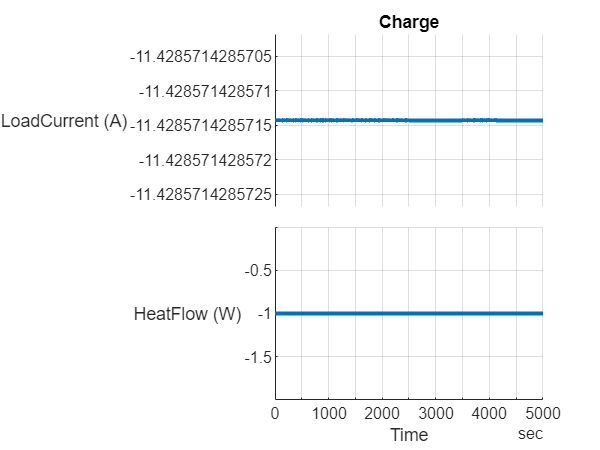

inpData = Charge(sigBuilder, ...
      LoadCurrent_Const_A = -1*CRateUnit_A, ...
      HeatFlow_Const_W = -1, ...
      InitialSOC_pct = ini_SOC_pct, ...
      InitialCharge_Ahr = ini_Chg_Ahr, ...
      InitialTemperature_degC = ini_Temp_degC, ...
      StopTime = seconds(5000) );

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, "StopTime",num2str(inpData.Options.StopTime_s));
t_end = inpData.Options.StopTime_s;

batteryHV_InputSignals = inpData.Signals;
batteryHV_InputBus = inpData.Bus;

assert(inpData.Options.InitialCharge_Ahr == ini_Chg_Ahr)
initial.hvBattery_Charge_Ahr = inpData.Options.InitialCharge_Ahr;

ambient.temp_K =  273.15 + inpData.Options.InitialTemperature_degC;
initial.hvBattery_Temperature_K = ambient.temp_K;

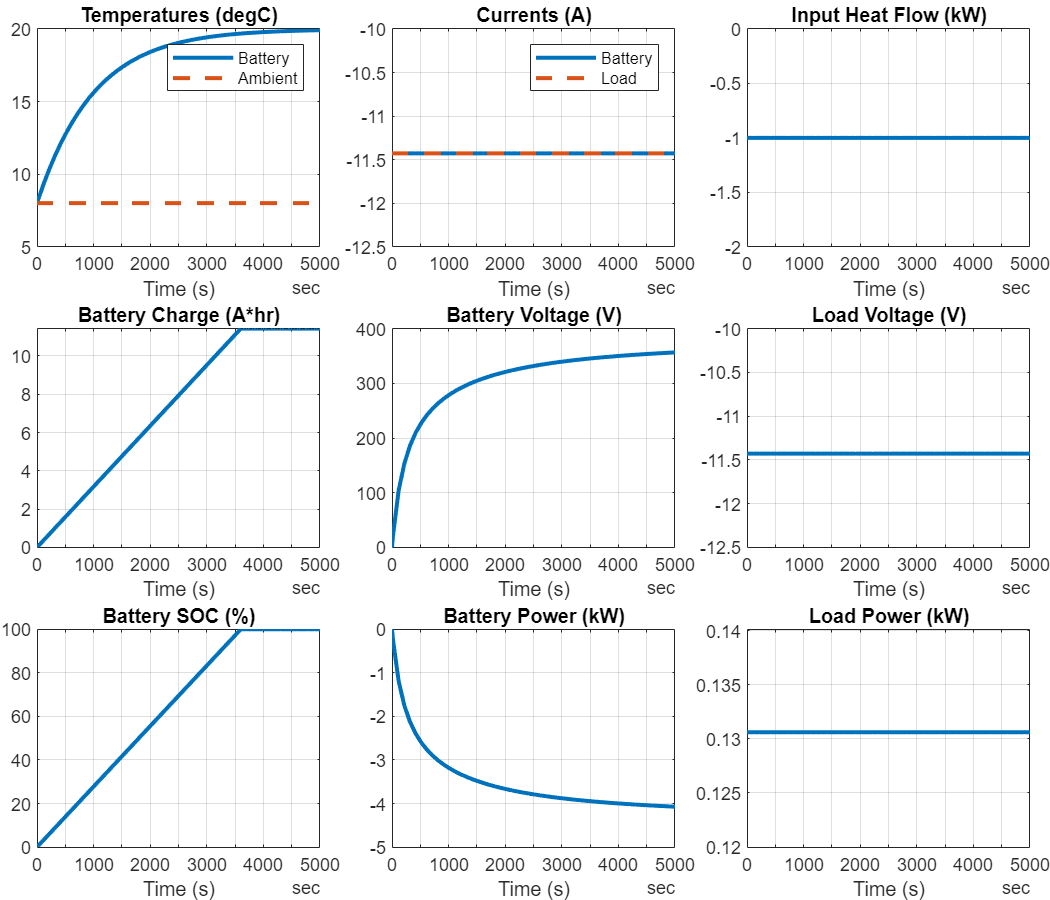

simOut = sim(simIn);

logged_signals = extractTimetable(simOut.logsout);
BatteryHV_plotResults(logged_signals);

*Copyright 2020-2022 The Mathworks, Inc.*